# TrainingSet Pre-Processing 

## Pre-process

clear; clc; close all; 

% TODO: Check if file exists for creating the DS 
dataStore = createDataStore(); 
save("data/dataStore", "dataStore"); 
disp("Check the DataStore in Data Laber App...")

Check the DataStore in Data Laber App...


% get datase 

load("data/dataset.mat");  % import gTruth

% Ground Truth variable 
gTruth

gTruth =   groundTruth with properties:

          DataSource: [1×1 groundTruthDataSource]
    LabelDefinitions: [2×5 table]
           LabelData: [3×2 table]


% Create the fucking dataset >:v
[imds, blds] = objectDetectorTrainingData(gTruth); 


ObjectDetectionDatastore = combine(imds, blds);


% Create Training image :'V 
% 1 + 4 + n_c = 5 + 2 = 7
% 270x270 => cell 15 v: 
% tensor_vector = 18x18x7

img = imds

img =   ImageDatastore with properties:

                       Files: {
                              '/Users/amorales/Documents/robotics/robocup/data/imgs/a.jpg';
                              '/Users/amorales/Documents/robotics/robocup/data/imgs/b.jpg';
                              '/Users/amorales/Documents/robotics/robocup/data/imgs/c.jpg'
                              }
                     Folders: {
                              '/Users/amorales/Documents/robotics/robocup/data/imgs'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


ans =    270   480     3


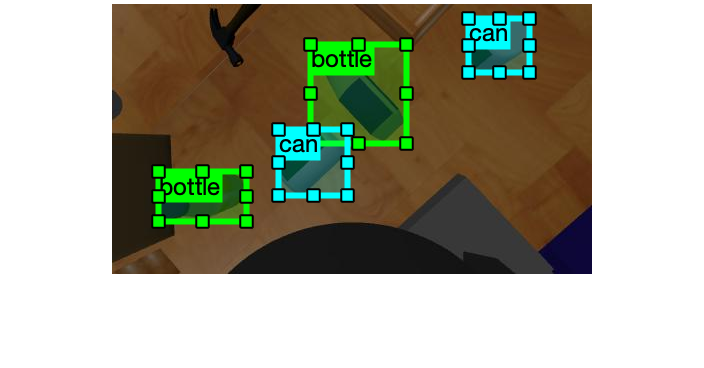

ans =    270   480     3


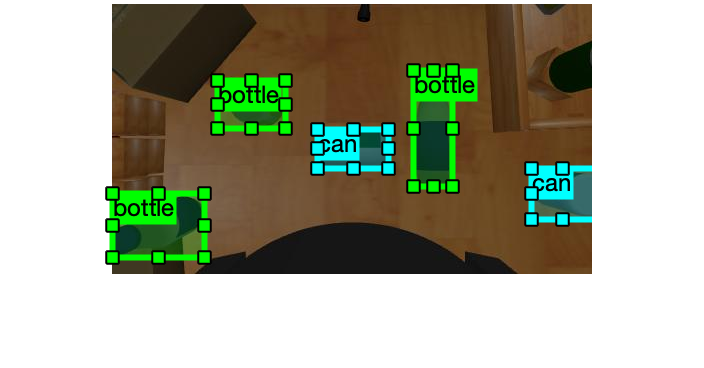

ans =    270   480     3


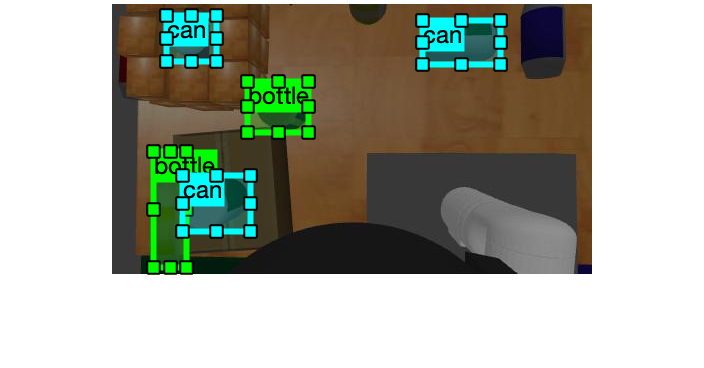


[nImgs, nColumns]= size(blds.LabelData);

for img_index = 1:nImgs
    % image scene 
    path_img = imds.Files{img_index}; 
    img_scene = imread(path_img); 
    size(img_scene)
    figure;
    imshow(img_scene);
    hold on; 
    
    % Bounding Boxes 
    
    bbox   = blds.LabelData{img_index, 1};
    labels = blds.LabelData{img_index, 2};
    
    x = bbox(1, 1); y = bbox(1, 2); 
    w = bbox(1, 3); h = bbox(1, 4); 
    
    for roi = 1:length(bbox)
        % draw label
        label = char(labels(roi)); 
        
        if label == "bottle"
            color = [0, 255, 0] / 255;
        elseif label == "can" 
            color = [0, 255, 255] / 255;
        else 
            color = [255, 255, 0] / 255;
        end
        drawrectangle("Color", color , "Label", label, "Position", bbox(roi, :)); 
    end 
    
end

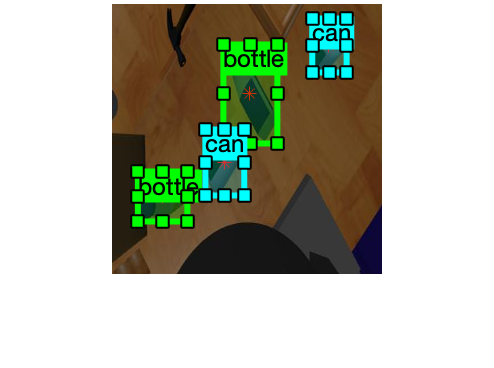

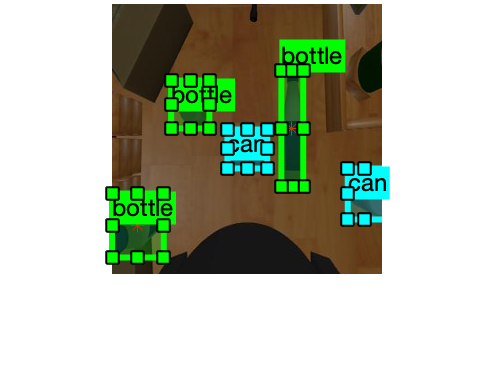

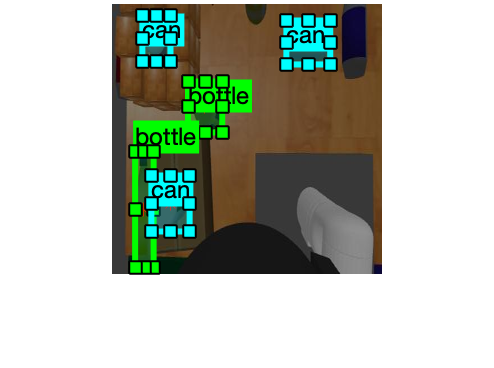


% Ahora las grillas del Peñon v: 
% find center :V 
% create output vector :VVVVVV

cell_dim = [1, 1] * 15; 
img = imresize(img_scene, [270,270]); 
imgDim = size(img); 
gridDims = imgDim(1:end - 1) ./ cell_dim;  

wFactor = 270/480;

numCategories = 2; 

% 1 + 4 + n_c = 5 + 2 = 7
cellDepth = 1 + 4 + numCategories; 
y_output = zeros([gridDims, cellDepth]);


[nImgs, nColumns]= size(blds.LabelData);
centroids = zeros([size(bbox), 3]) ;

y_stack = zeros([size(y_output), nImgs]); 

for img_index = 1:nImgs
    % image scene 
    path_img = imds.Files{img_index}; 
    img_scene = imread(path_img); 
    img_scene = imresize(img_scene, [270,270]); 
    figure;
    imshow(img_scene);
    hold on; 
    
    % Bounding Boxes 
    bbox   = blds.LabelData{img_index, 1};
    labels = blds.LabelData{img_index, 2};
    
    % Correct bounding box position due to resizing ----
    % Take the bbox matrix and multiply just the 
    % horizontal components (x, w) with a shrinking factor 
    % from the img resize (wFactor). 
    
    n = length(bbox); % Amount of Bounding Boxes 
    o_t = ones(1, n)'; 
    z_t = zeros(1, n)';
    
    % Resize correction
    t = [o_t, z_t, o_t, z_t] * wFactor + [z_t, o_t, z_t, o_t]; 
    bbox = bbox .* t; 
    
 
    % Draw each bounding box 
    for roi = 1:length(bbox)
        % draw label
        label = char(labels(roi)); 
        
        category_classifier = [0, 0];
        % Color definition 
        if label == "bottle"
            color = [0, 255, 0] / 255;
            category_classifier = [1, 0];
        elseif label == "can" 
            color = [0, 255, 255] / 255;
            category_classifier = [0, 1];
        else 
            color = [255, 255, 0] / 255;
        end
        
        
        % ROI rectangle draw
        drawrectangle("Color", color , "Label", label, "Position", bbox(roi, :)); 
        
           x = bbox(roi, 1); y = bbox(roi, 2); 
           w = bbox(roi, 3); h = bbox(roi, 4); 
    
        % getCenter ;
        centroid = [x , y] + [w, h] * 0.5;
        centroid = floor(centroid);
        hold on; 
        plot(centroid(1), centroid(2), '*r'); 
        
        index_relative = floor(centroid/cell_dim(1));
        pos_relative = mod(centroid, cell_dim) / cell_dim(1);
        dim_relatives = [w, h] / 270;
        
        y_output(index_relative(1), index_relative(2), :) = [1 category_classifier pos_relative dim_relatives];
        
    end 
    
    y_stack(:, :, :, img_index) = y_output; 
    
end

save("data/TrainingSet", "y_stack") % Save the output vectors 